## ANALYSIS OF MORE THAN 1 SAMPLE

GENERATE DIFFERENT OBJECTS FOR THE DIFFERENT SAMPLES

1st sample is added and included in SPOTS1

decoded_file = 'G:\Analysis_of_samples\Jessica_tsne_TUMOR_170320\880842_QT_0.4_0.005_details.csv';
image = 'G:\Analysis_of_samples\Jessica_tsne_TUMOR_170320\880842_1.jpg';    % important for size
scale=0.2; %
%% do not modify
% load
SPOTS1=ISS_getspots(decoded_file);
SPOTS1.image=image;
SPOTS1.scale=scale;
SPOTS1.output_directory='G:\Jessica_tsne_TUMOR_170320\outputfolder'; %YOU CAN MODIFY THIS MAYBE
mkdir(SPOTS1.output_directory);

Addding the second file in SPOTS2

decoded_file = 'G:\Analysis_of_samples\Jessica_tsne_TUMOR_170320\QT_0.4_0.005_details_900196_1.csv';
image = 'G:\Analysis_of_samples\Jessica_tsne_TUMOR_170320\900196_1.jpg';    % important for size
scale=0.2;
%% do not modify
% load
SPOTS2=ISS_getspots(decoded_file);
SPOTS2.image=image;
SPOTS2.scale=scale;
SPOTS2.output_directory='G:\outputfolder';
mkdir(SPOTS2.output_directory);

**IN CASE YOU NEED MORE SAMPLES, YOU CAN COPY THE CHUNK OF CODE THAT YOU HAVE JUST RAN CHANGE SPOTS3 by SPOTS4,SPOTS...**

And then we combine them into a big object (note that if you have added more samples you need to add them here as well)

ALLSPOTS.SPOTS1=SPOTS1;
ALLSPOTS.SPOTS2=SPOTS2;

## Creating overlapping means

We do capture the expression of different regions in the tissue by binning it and capturing the expression profile. In this case *OverlappingBins* generates bins that overlap between them. In this case, we can specify on 2nd position distance between spots in pixels and on 3rd position the radius of the bin

distance=400;
radius=500;
ALLEXPRESSION=ISS_OverlappingBins_moresamples(ALLSPOTS,distance,radius)

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20

    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125



ALLEXPRESSION = struct with fields:
           exp: [4952×92 double]
           loc: [4952×2 double]
      genename: {92×1 cell}
    hexbinsize: 120
        sample: [4952×1 double]
         image: {'G:\Analysis_of_samples\Jessica_tsne_TUMOR_170320\880842_1.jpg'  'G:\Analysis_of_samples\Jessica_tsne_TUMOR_170320\900196_1.jpg'}
         scale: {[0.2000]  [0.2000]}


### **Tsne representation **

In order to represent the heterogeneity in a tissue, we use binned or segmented data to perform 3D tSNE, representing each of the dimensions in RGB scale. Therefore, we are able to represent differentially expressed regions. We can select the genes going into the analysis

genes = 91×1 cell array
    {'ACTA2' }
    {'ACTB'  }
    {'ALDH1' }
    {'ALG8'  }
    {'APPBP2'}
    {'BAG1'  }
    {'BCL11a'}
    {'BCL2'  }
    {'BIRC5' }
    {'BRCA1' }
    {'BRCA2' }
    {'BRF2'  }
    {'CCL18' }
    {'CCNB1' }
    {'CCND1' }
    {'CD163' }
    {'CD24'  }
    {'CD68'  }
    {'CDH1'  }
    {'CDH2'  }
    {'CLDN3' }
    {'CLDN4' }
    {'CLDN7' }
    {'COL3A1'}
    {'CTNNB' }
    {'CTSL2' }
    {'CUX1'  }
    {'CXCL12'}
    {'CXCL14'}
    {'EGFR'  }


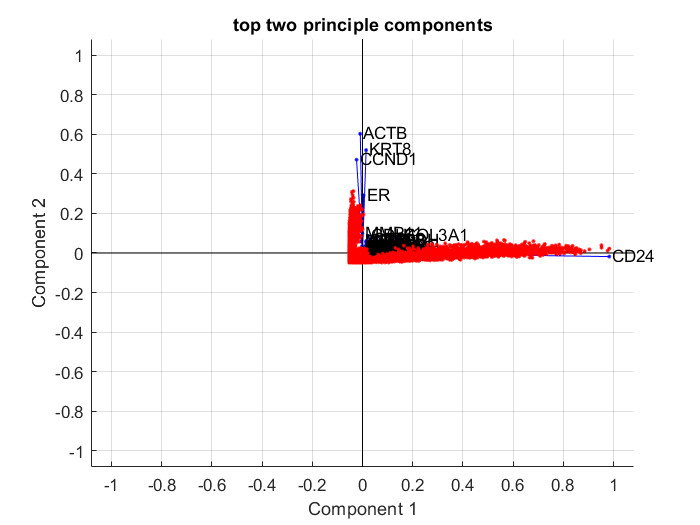


|==============================================|
|   ITER   | KL DIVERGENCE   | NORM GRAD USING |
|          | FUN VALUE USING | EXAGGERATED DIST|
|          | EXAGGERATED DIST| OF X            |
|          | OF X            |                 |
|==============================================|
|       20 |    3.218747e+01 |    4.437628e-07 |
|       40 |    2.714669e+01 |    7.839982e-05 |
|       60 |    2.282204e+01 |    8.911059e-05 |
|       80 |    2.156359e+01 |    8.259148e-05 |

|==============================================|
|   ITER   |  KL DIVERGENCE  |    NORM GRAD    |
|          |    FUN VALUE    |                 |
|==============================================|
|      100 |    3.836392e+00 |    3.074364e-05 |
|      120 |    3.366022e+00 |    1.649705e-05 |
|      140 |    3.102109e+00 |    1.423008e-05 |
|      160 |    2.909939e+00 |    8.455808e-06 |
|      180 |    2.761967e+00 |    7.426492e-06 |
|      200 |    2.643929e+00 |    6.807898e-06 |
|      220 |    2.

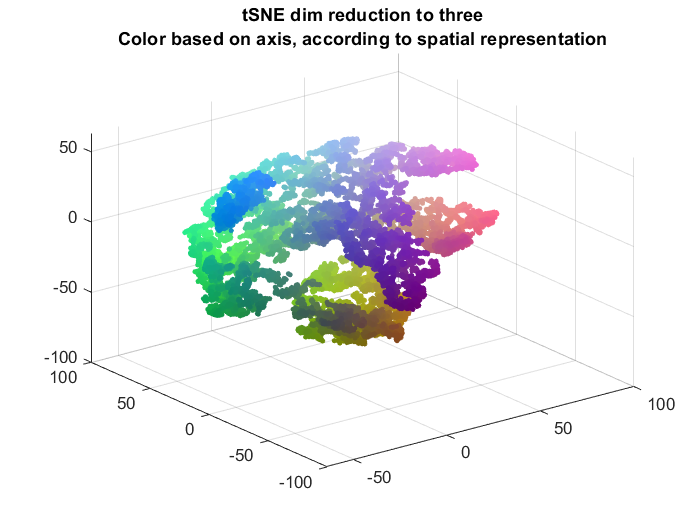

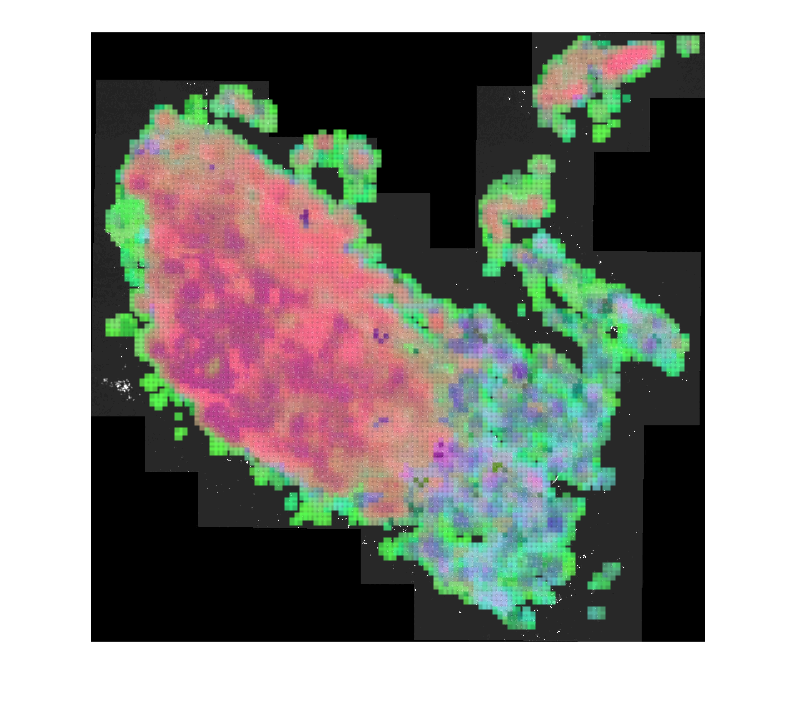

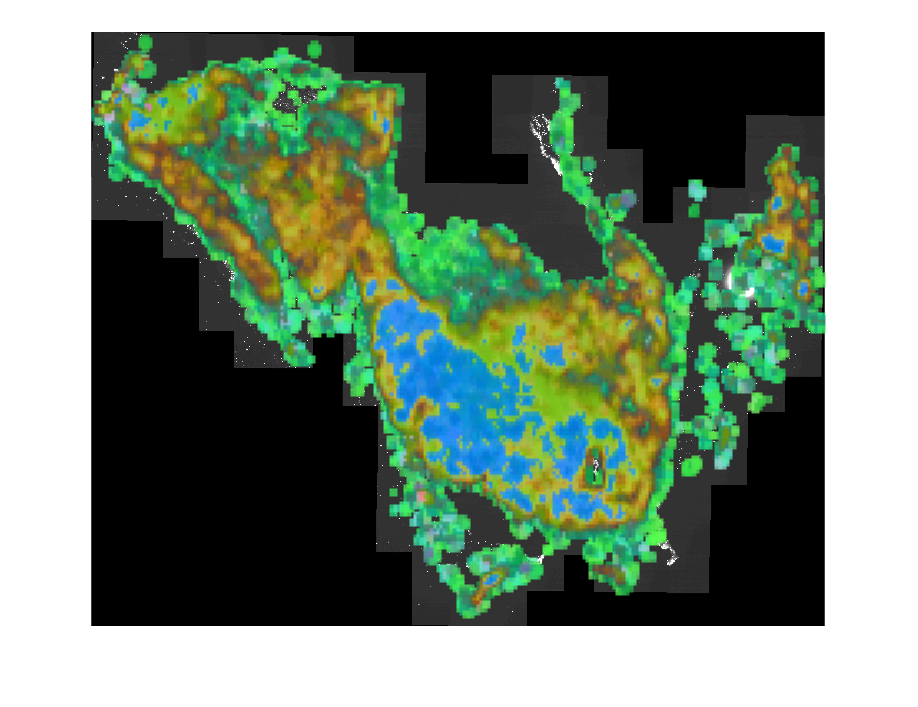

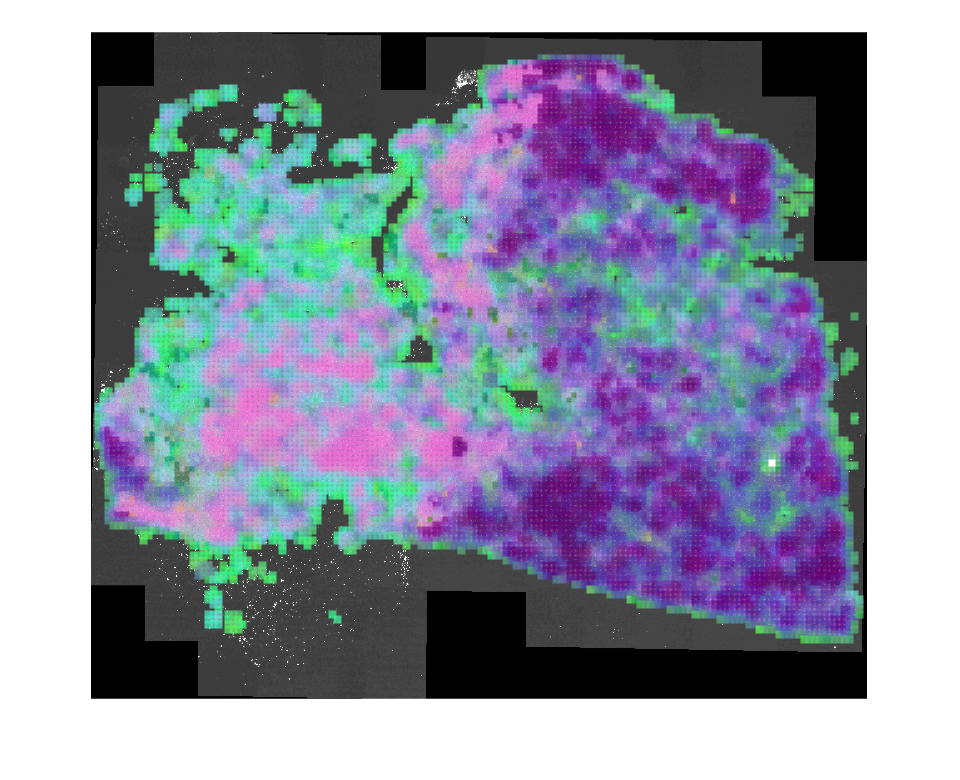

ISS_tsneRGB_several_samples(ALLEXPRESSION,ALLSPOTS.SPOTS1,10)

## Hierarchical clustering data

Hierarchical custering performs a clustering based on a hierarchical strategy, by dividing data in binary categories consecutively. In this case, the number of categories desired needs to be specified by the user.

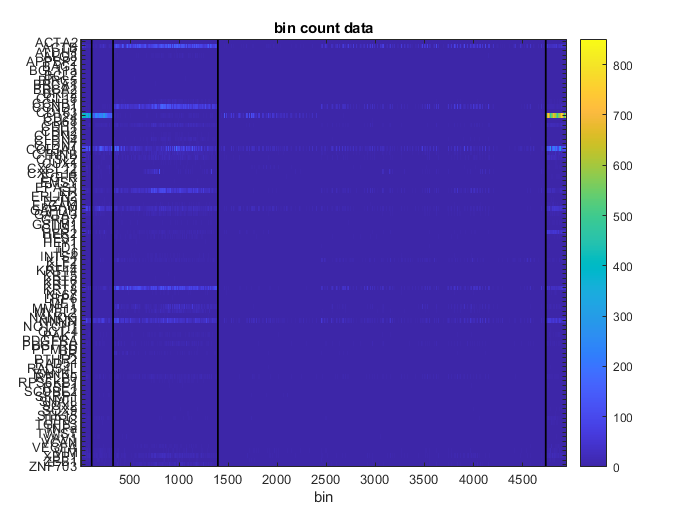

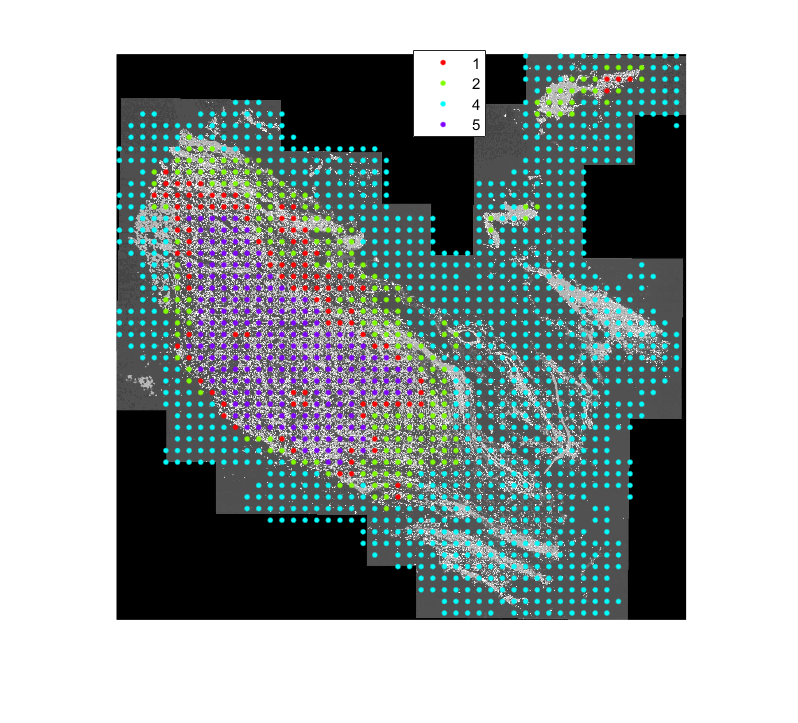

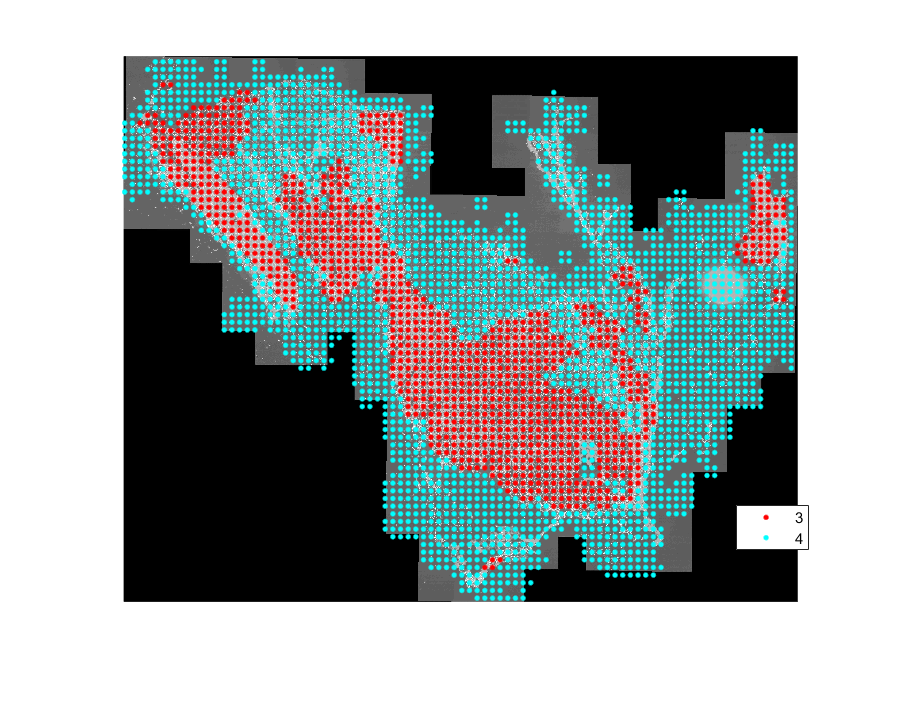

ALLCELLS = struct with fields:
    sample1: [1×1 struct]
    sample2: [1×1 struct]


[ALLCELLS]=ISS_Clustering(ALLEXPRESSION,5,'hierarchical')

## kMeans clustering

Starting kmeans clustering with 500 replicates..


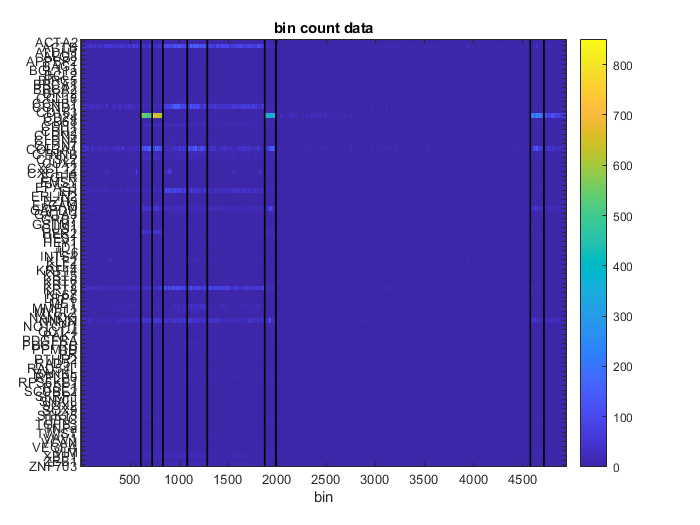

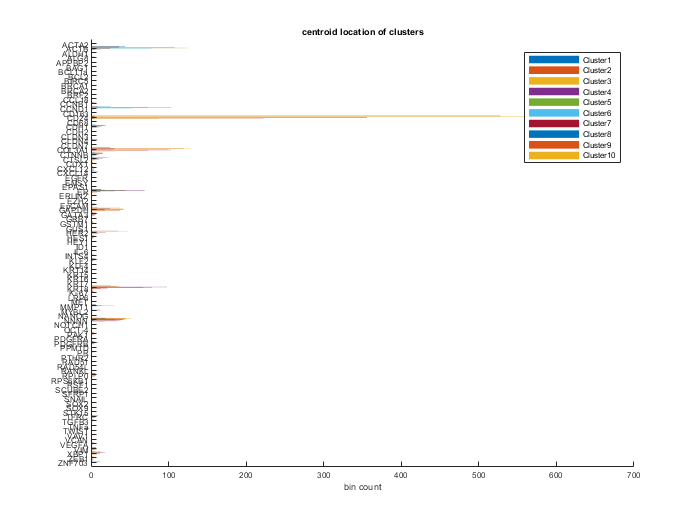

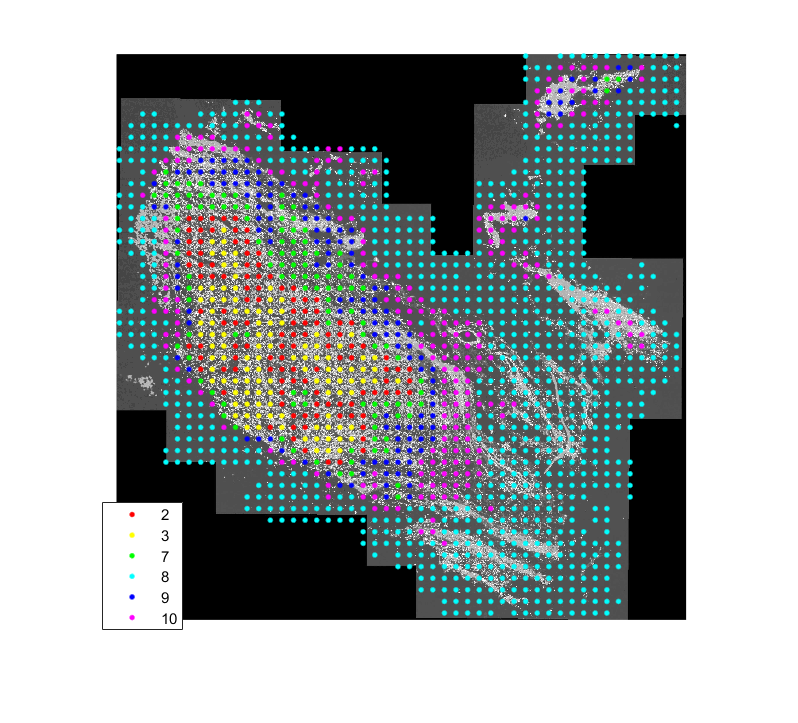

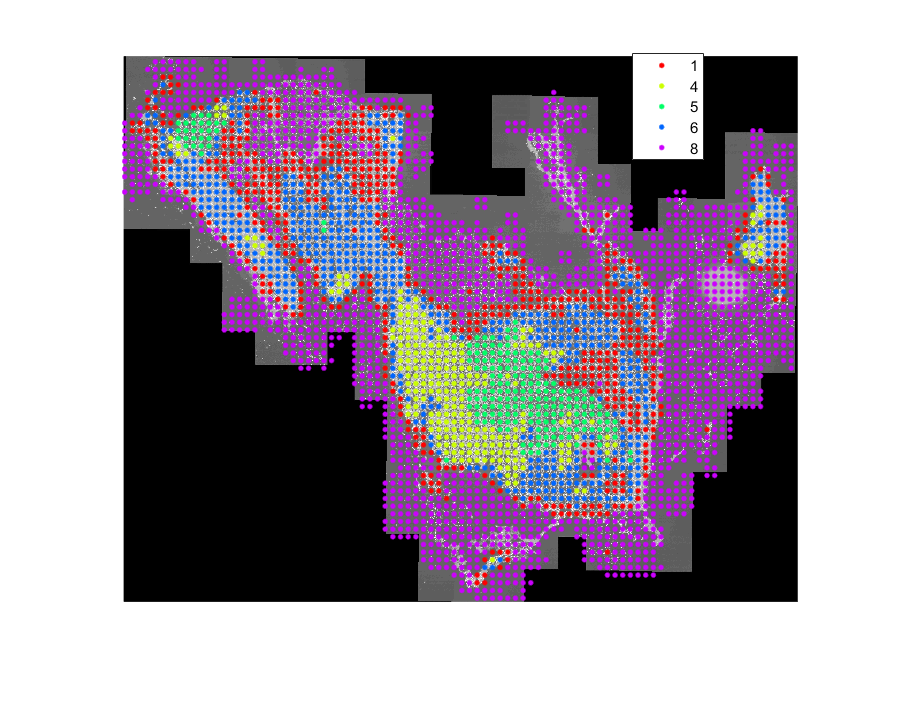

ALLCELLS = struct with fields:
    sample1: [1×1 struct]
    sample2: [1×1 struct]


[ALLCELLS]=ISS_kMeans(ALLEXPRESSION,10)

UNDER CONSTRUCTION

BI=ISS_Enviroment_neighbors_moresamples(SUPEROBJECT,radius)

     1

     1

     1

     1



BI = struct with fields:
           exp: [4×105 double]
           loc: [4×2 double]
      genename: {105×1 cell}
    hexbinsize: 6
        sample: [4×1 double]
         image: {'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'  'G:\DIPG pciseq\Sample2\Base_2_aligned-1.tif'}
         scale: {[1]  [1]  [1]  [1]}
